clc
clear
startupSwan
problem = 3; %1 = 4DOF spring, 2 =) 1000DOF Spring, 3 = testingEIFEM matrices

solver = Testing_LOBPCG(problem);

% Solver Controls:
solver.b      = 5;        % number of modes 
solver.use_precond = true;
solver.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver.tol    = 1e-8;    % residual tolerance
solver.maxit  = 20000;       % max iterations
solver.verbose = false;
solver.precond_type = 'eifem'
results = solver.run_demo();

%% Jacobi with EIFEM initial guess 
solver2 = Testing_LOBPCG(problem);
solver2.b      = 5;        % number of modes 
solver2.use_precond = true;
solver2.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver2.tol    = 1e-8;    % residual tolerance
solver2.maxit  = 20000;       % max iterations
solver2.verbose = false;
solver2.precond_type ='jacobi'
results2 = solver2.run_demo();

%% No Precond with Random initial guess 
solver3 = Testing_LOBPCG(problem);
solver3.b      = 5;        % number of modes 
solver3.use_precond = false;
solver3.use_physical_x = false; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver3.tol    = 1e-8;    % residual tolerance
solver3.maxit  = 20000;       % max iterations
solver3.verbose = false;
solver3.precond_type ='none'
results3 = solver3.run_demo();

%% No Prec with EIFEM initial guess 
solver4 = Testing_LOBPCG(problem);
solver4.b      = 5;        % number of modes 
solver4.use_precond = false;
solver4.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver4.tol    = 1e-8;    % residual tolerance
solver4.maxit  = 20000;       % max iterations
solver4.verbose = false;
solver4.precond_type ='none'
results4 = solver4.run_demo();

pause = 1;


%% No Precond with EIFEM initial guess 
solver4 = Testing_LOBPCG(problem);
solver4.b      = 5;        % number of modes 
solver4.use_precond = false;
solver4.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
solver4.tol    = 1e-8;    % residual tolerance
solver4.maxit  = 20000;       % max iterations
solver4.verbose = false;
solver4.precond_type ='eifem'
results4 = solver4.run_demo();



% Define tolerance threshold (values below this are considered converged/padding)
tol = 1e-8; 
tol2 = 1e-7

tol2 = 1.0000e-07

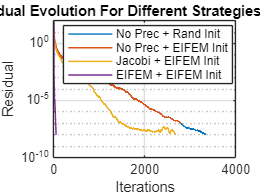

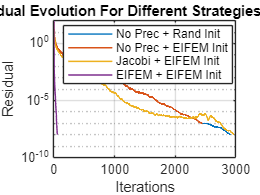

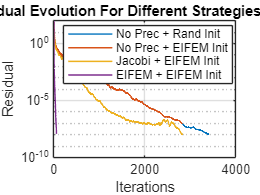

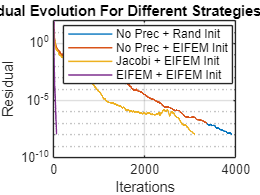

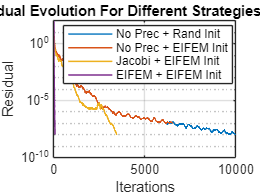

for i = 1:solver.b
    figure(i)
    
    % --- Strategy 1: No Prec + Rand Init (results3) ---
    raw_res1 = results3.history.rnorm(:,i);
    % Filter: keep only values strictly greater than tolerance
    res_1 = raw_res1(raw_res1 > tol); 
    x_axis1 = 1:length(res_1);

    % --- Strategy 2: No Prec + EIFEM Init (results4) ---
    raw_res2 = results4.history.rnorm(:,i);
    res_2 = raw_res2(raw_res2 > tol2);
    x_axis2 = 1:length(res_2);

    % --- Strategy 3: Jacobi + EIFEM Init (results2) ---
    raw_res3 = results2.history.rnorm(:,i);
    res_3 = raw_res3(raw_res3 > tol);
    x_axis3 = 1:length(res_3);

    % --- Strategy 4: EIFEM + EIFEM Init (results) ---
    raw_res4 = results.history.rnorm(:,i);
    res_4 = raw_res4(raw_res4 > tol);
    x_axis4 = 1:length(res_4);

    % Plotting with dynamic lengths
    semilogy(x_axis1, res_1, ...
             x_axis2, res_2, ...
             x_axis3, res_3, ...
             x_axis4, res_4, 'LineWidth', 1)
             
    xlabel('Iterations')
    ylabel('Residual')
    grid on
    title(['Residual Evolution For Different Strategies (Mode ' num2str(i) ')'])
    
    legend('No Prec + Rand Init', ...
           'No Prec + EIFEM Init', ...
           'Jacobi + EIFEM Init', ...
           'EIFEM + EIFEM Init', ...
           'Location', 'best') 
end

for i = 1:solver.b
    figure
    
    % --- Strategy 1: No Prec + Rand Init (results3) ---
    raw_res1 = results3.history.rnorm(:,i);
    % Filter: keep only values strictly greater than tolerance
    res_1 = raw_res1(raw_res1 > tol); 
    x_axis1 = 1:length(res_1);

    % --- Strategy 2: No Prec + EIFEM Init (results4) ---
    raw_res2 = results4.history.rnorm(:,i);
    res_2 = raw_res2(raw_res2 > tol);
    x_axis2 = 1:length(res_2);

    
    % Plotting with dynamic lengths
    semilogy(x_axis2, res_2, ...
             x_axis1, res_1, ...
             'LineWidth', 1)
             
    xlabel('Iterations')
    ylabel('Residual')
    grid on
    title(['Residual Evolution For Different Strategies (Mode ' num2str(i) ')'])
    
    legend('No Prec + Rand Init', ...
           'No Prec + EIFEM Init', ...
           'Location', 'best') 
end

## Testing Direct Eigs CPU Time vs Initial Guess

solverCase2 = Testing_LOBPCG(3);
K = solverCase2.K; 
M = solverCase2.M;
eigs_to_get = 1;
[V, D] = eigs(K, M, eigs_to_get, 'smallestabs');
[theta, p] = sort(real(D), 'ascend');
Vtrue = V(:, p);
% Preallocate matrix to store runtimes
runTime = zeros(15, 200); 
sigma = 0.1:0.05:0.95;
for i = 1:size(sigma,2)
    for j = 1:200
        perturb = (1-sigma(i)) + sigma(i) * (2*rand(size(Vtrue)) - 1);
        X = perturb(:,1:eigs_to_get) .* Vtrue(:,1:eigs_to_get); %perturb to represent coarse
        tStart = tic;  % start timer
        [V, D] = eigs(K, M, eigs_to_get, 'smallestabs','StartVector',X(:,1));
        [theta, p] = sort(real(D), 'ascend');
        V = V(:, p);

        runTime(i, j) = toc(tStart);  % store elapsed time
    end
end
figure 
for i = 1:size(runTime,1)
    avgRunTime(i) = mean(runTime(i,:))
end



% 
% figure
% x_axis = 1:length(results.history.rnorm);
% for i = 1:solver.b
%     semilogy(x_axis, results.history.rnorm(:,i), 'LineWidth', 1)
%     hold on
% end
% xlabel('Iterations')
% ylabel('Residual')
% grid on
% title('Residual Evolution Big Problem')
% % Automatically make legend labels
% legend(arrayfun(@(k) sprintf('Mode %d', k), 1:solver.b, 'UniformOutput', false), ...
%        'Location', 'best')
 

% figure
% x_axis = 1:800;
% for i = 1:5
%     semilogy(x_axis, results.history.rnorm(1:800,i), 'LineWidth', 1)
%     hold on
% end
% xlabel('Iterations')
% ylabel('Residual')
% grid on
% title('Residual Evolution Big Problem')
% legend(arrayfun(@(k) sprintf('Mode %d', k), 1:5, 'UniformOutput', false), ...
%        'Location', 'best')
% 

## Testing Direct Eigs CPU Time vs Initial Guess


n  = 500;
K  = diag(1:n);           % diagonal SPD
M  = speye(n);
k  = 1;                   % smallest eigenvalue (1)
opts.tol   = 1e-8;
opts.maxit = 1000;
opts.disp  = 2;           % print ARPACK iterations

% Bad initial guess: orthogonal to e1
v0_bad       = zeros(n,1);
v0_bad(2:end)= 1;         % no component in direction of eigenvector e1
opts_bad     = opts;
opts_bad.v0  = v0_bad;

% Good initial guess: almost the true eigenvector
v0_good      = zeros(n,1);
v0_good(1)   = 0.999;
v0_good(2)   = 0.001;
opts_good    = opts;
opts_good.v0 = v0_good;

fprintf('=== Bad initial guess ===\n');

=== Bad initial guess ===


[Vb,Db] = eigs(K,M,k,'smallestreal',opts_bad);


=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 1 eigenvalues of type 'smallestreal'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 1000
  Tolerance: 1e-08
  Subspace Dimension: 20

Find eigenvalues of R'\(A*(R\x)) = lambda*x, with B = R'*R.

--- Start of Krylov-Schur method ---
Iteration    1: 0 of 1 eigenvalues converged. Smallest non-converged residual 1.4e+00 (tolerance 1.0e-08).
Iteration    2: 0 of 1 eigenvalues converged. Smallest non-converged residual 9.9e-01 (tolerance 1.0e-08).
Iteration    3: 0 of 1 eigenvalues converged. Smallest non-converged residual 6.3e-01 (tolerance 1.0e-08).
Iteration    4: 0 of 1 eigenvalues converged. Smallest non-converged residual 3.8e-01 (tolerance 1.0e-08).
Iteration    5: 0 of 1 eigenvalues converged. Smallest non-converged residual 1.7e-01 (tolerance 1.0e-08).
Iteration    6: 0 of 1 eigenvalues converged


fprintf('\n=== Good initial guess ===\n');


=== Good initial guess ===


[Vs,Ds] = eigs(K,M,k,'smallestreal',opts_good);


=== Generalized eigenvalue problem A*x = lambda*B*x ===

The eigenvalue problem is real symmetric.
Matrix B is symmetric positive (semi-)definite.

Computing 1 eigenvalues of type 'smallestreal'.


Parameters passed to Krylov-Schur method:
  Maximum number of iterations: 1000
  Tolerance: 1e-08
  Subspace Dimension: 20

Find eigenvalues of R'\(A*(R\x)) = lambda*x, with B = R'*R.

--- Start of Krylov-Schur method ---
Iteration    1: 1 of 1 eigenvalues converged.
